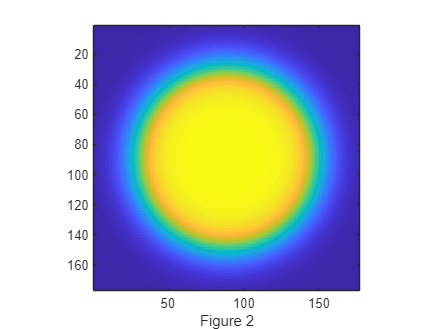

%graph ideal image 
D=124;          % Diameter
w=13.5;         % Width
ss=2*fix(D/2+4*w/2)-1;          % size of ideal particle image
os=(ss-1)/2;                    % (size-1)/2 of ideal particle image
[xx yy]=ndgrid(-os:os,-os:os);  % ideal particle image grid
r=hypot(xx,yy);                 % radial coordinate
h=figure(2); set(h,'Position',[100 100 400 400],'Color',[1 1 1]);
simage(ipf(r,D,w));
xlabel('Figure 2');

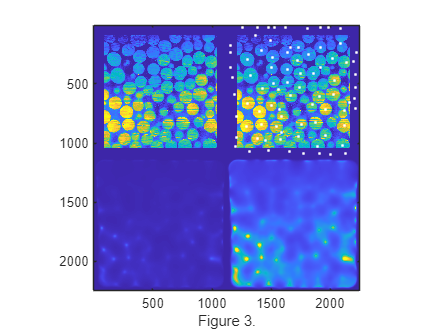

load('dawn.m',"-mat")
imgd=imcomplement(imgd);
raw=imgd(1:952,1:952);  % load image
[Nx Ny]=size(raw);       % image size

%to view histogram histogram(imgd) & normalized one:histogram(ri)
hi=0.75;  % hi and lo values come the image histogram
lo=0.35;   % hi/lo=typical pixel value outside/inside
ri=(hi-double(raw))/(hi-lo);  % normalize image

D=123;          % Diameter
w=13.5;         % Width
ss=2*fix(D/2+4*w/2)-1;          % size of ideal particle image
os=(ss-1)/2;                    % (size-1)/2 of ideal particle image
[xx yy]=ndgrid(-os:os,-os:os);  % ideal particle image grid
r=hypot(xx,yy);                 % radial coordinate

Cutoff=0.7;      % minimum peak intensity
MinSep=5;      % minimum separation between peaks
[Np px py]=findpeaks(1./chiimg(ri,ipf(r,D,w)),1,Cutoff,MinSep);  % find maxima

h=figure(2); set(h,'Position',[100 100 600 600],'Color',[1 1 1]);
simage([100*zerofill(ri,2*os,2*os) 100*zerofill(ri,2*os,2*os); 1./chiimg(ri,ipf(r,D,w)) 8*1./chiimg(ri,ipf(r,D,w))]); caxis([0 100])
hold on;
plot(py+2*os+Ny,px,'w.');
hold off;
xlabel('Figure 3.');